load classdata.mat

%Creates a cell array with the names of the people
Names = cell(1,66);
for i = 1:66
    Names(1,i) = y.name(1,2*i);    
end

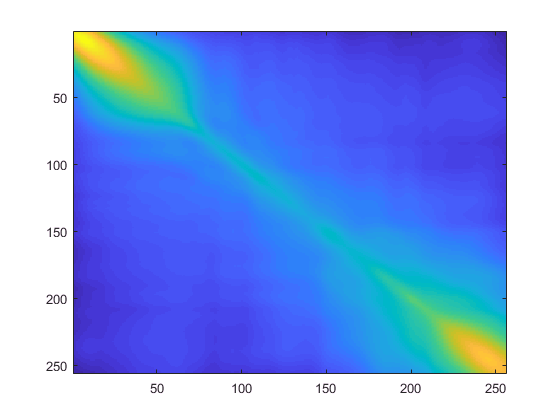

AverageClassFaces = zeros(256,256,66);
for i = 1:66
    AverageClassFaces(:,:,i) = (grayfaces(:,:,2*i)+grayfaces(:,:,2*i-1))/2 ;
end

TotalAverageFace = zeros(256,256);
for i = 1:132
    TotalAverageFace = TotalAverageFace + grayfaces(:,:,i);
end
TotalAverageFace = TotalAverageFace./132;

Sb = zeros(256,256);
for i = 1:66
    Sb = Sb + (2*(AverageClassFaces(:,:,i)-TotalAverageFace)*(AverageClassFaces(:,:,i)-TotalAverageFace).') ;
end
imagesc(Sb)

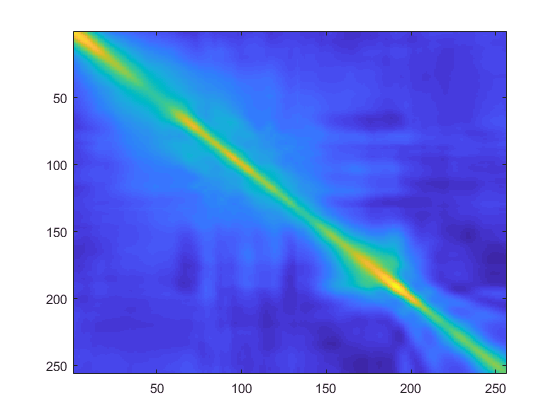


Sw = zeros(256,256);
for i = 1:66
    InsideWithin2 = zeros(256,256);
   for k = 1:2
       InsideWithin1 = (grayfaces(:,:,2*i-2+k) - AverageClassFaces(:,:,i)) * (grayfaces(:,:,2*i-2+k) - AverageClassFaces(:,:,i)).' ;
       InsideWithin2 = InsideWithin2 + InsideWithin1;
   end
    Sw = Sw + InsideWithin2;
end
imagesc(Sw)

% Find W_opt